**Code for Spectrogram**

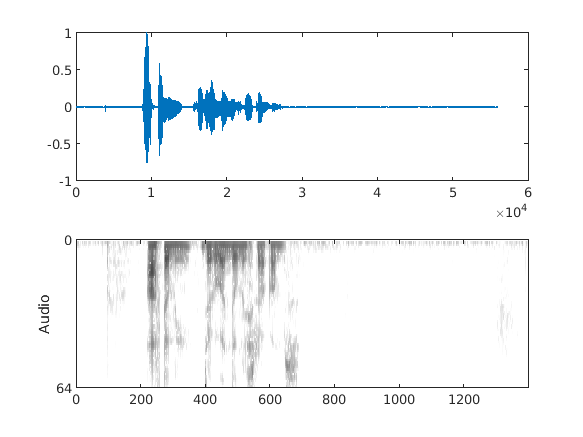

f=8000;
x=[];
% f=linspace(-fs/2,fs/2,length(t1));
[x,fs]=audioread('M017AA1S03.wav');

%%

signal=resample(x(:,1),f,fs);
signal = signal - mean(signal);
signal = signal./max(abs(signal));
N=length(signal);

win_temp=25.6;                      % window length in miliseconds
win_len=fix(win_temp*fs*10^-3);     % window length in samples
overlap=0.75;                       % overlap between frames


t1=(1:length(signal));
% t=0:tau/f:(tau-1/f);

%
L=5/1000*fs; %%%%%%%%%%%%%framesize. Here the numeral is in millisecond
frameshift=(L/2);
window = hann(L);
%convert to 2^n by zero padding
l=log2(L);
l1=ceil(l);
fft_len=2^l1;
fft_half=fft_len/2+1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
k=1;
for i=1:frameshift:N-L+1
    segmentSignal(:,k)=signal(i:i+L-1).*window(1:L);
    k=k+1;
end
for i=1:size(segmentSignal,2)
    STFT(:,i)=fft(segmentSignal(:,i),fft_len);
end

NumberOfFrames = k-1;
STFTMag=sqrt(STFT.*conj(STFT));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t1=(1/f:1/f:N/f);

figure(1);
a(1) = subplot(211);
plot(signal);
a(2) = subplot(212);
% figure('Color',[1 1 1]);
imagesc(imcomplement(real(flipud(20*log10((STFTMag)))))); 
colormap gray;
box on;

% xlabel('Time(s)')
set(gca,'LooseInset',get(gca,'TightInset'))
ylim([0 fft_half-1]);
%xlim([0 length(t1(:,15))])
xlim([0 NumberOfFrames])

set(gca,'YTick',[0 fft_half-1]) %figure 7 0:64:fft_half-1

ylabel('Audio') % Figure 7 ylabel('Frequency (kHz)')
caxis([-40 40])

**Narrow Band**

fs=16000

fs = 16000

t = 0:1/fs:length(x)/fs - 1/fs;
% Window length of 30 msec and step of 10 msec
figure; 
xlabel('Time (s)')
spectrogram(x,hamming(256),128)
title('Narrow Band')

**Wide Band**

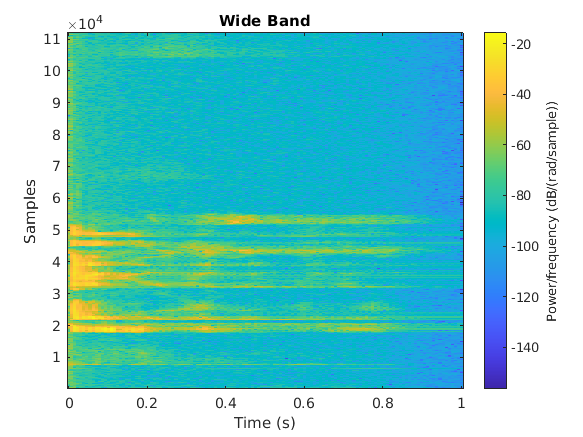

xlabel('Time (s)') 
title('Narrow Band')

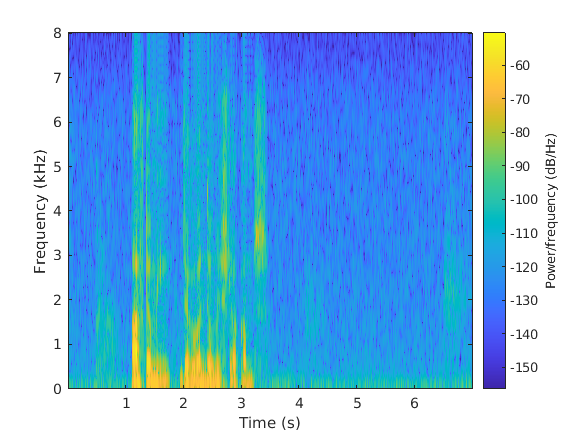

spectrogram(x, 5*10^(-3)*fs, 2*10^(-3)*fs, 1024, fs, 'yaxis')